# Cross-Tabulation

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads the data.

X = readmatrix("./data/data2.csv");
X = X(:, [1, 2]);
yCat = readmatrix("./data/data2.csv", OutputType="string");
yCat = categorical(yCat(:, 3));
whos X yCat

  Name        Size            Bytes  Class          Attributes

  X         600x2              9600  double                   
  yCat      600x1               818  categorical              



This code clusters the data into 2 groups using `kmeans` and visualizes the clusters.

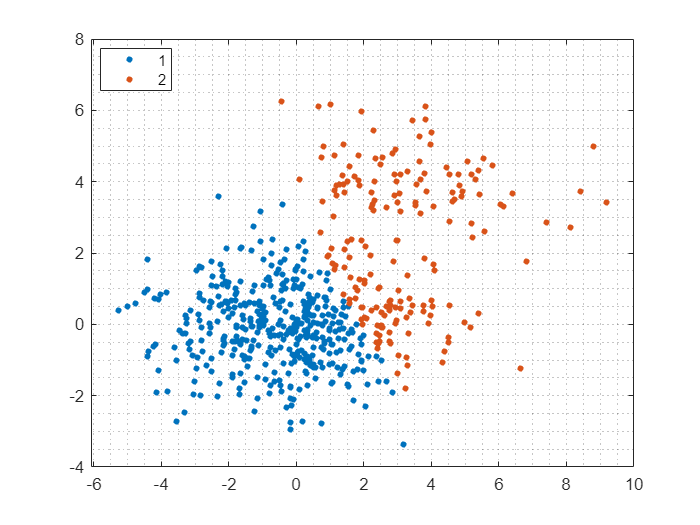

grp = kmeans(X, 2);
gscatter(X(:, 1), X(:, 2), grp)
grid minor

## Task 1

In some data sets, the observations already have a category associated with them. You can use the [`crosstab`](https://www.mathworks.com/help/stats/crosstab.html) function to study the distribution of clusters across the original categories.

`counts` `=` `crosstab``(``yCat``,``grp``)`

The first input to `crosstab` corresponds with the rows of `counts`, and the second input corresponds with the columns of `counts`.

cts = crosstab(yCat, grp)

cts =    409    91
     5    95


## Task 2

You can use the `heatmap` function to visualize the counts.

`heatmap``(``counts``)`

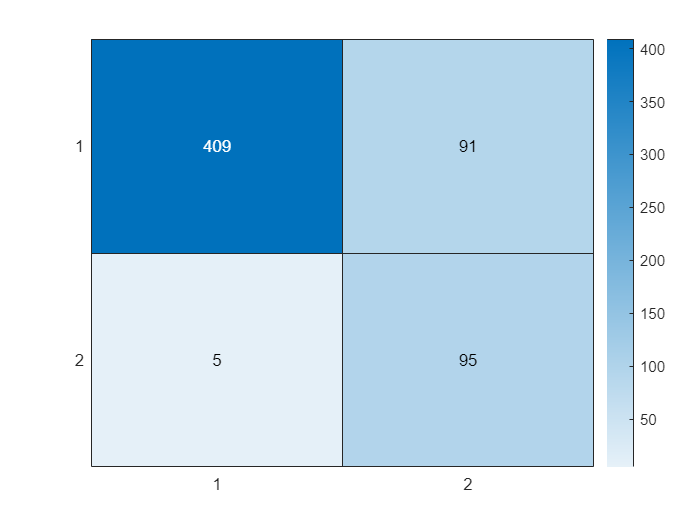

heatmap(cts)

## Task 3

You can label the original categories in the heatmap by using the `"YDisplayLabels"` property.

`heatmap``(``counts``,``...`

    `"``YDisplayLabels``"``,``categories``(``cats``)``)`

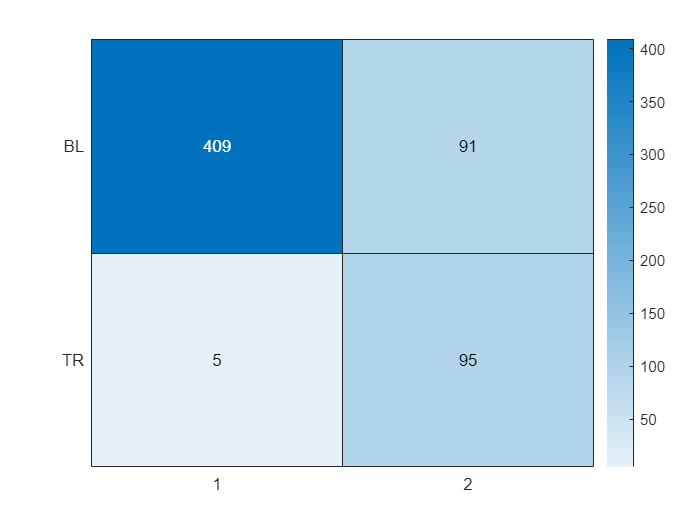

heatmap(cts, "YDisplayLabels", categories(yCat))